clc; close all; clear all; 

load(fullfile("Data","data_set.mat"));
load(fullfile("Data","wavelengths.mat"));

mean(mean(isnan(data_set{:,2:22})))

ans = 0.6287

X=data_set{:,22:end};
figure;
[coeff, score, latent, tsquared, explained, mu] = pca(X);

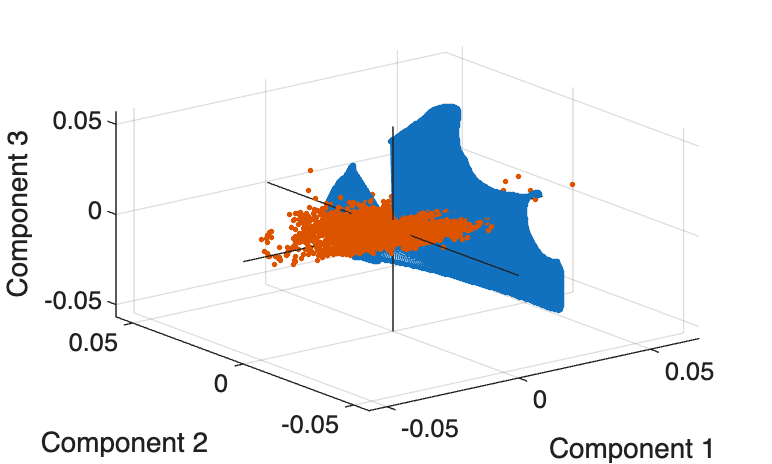


figure;
biplot(coeff(:,1:3), Scores=score(:,1:3));



var_visible= true; %set the visibility for the wavelength's contribution to the PCs
varl = findobj(gca,"Tag","varline");
varl.Visible=var_visible;
varm = findobj(gca,"Tag","varmarker");
varm.Visible=var_visible;
obsm = findobj(gca,"Tag","obsmarker");
%coordinates of points in biplot
varX= varm.XData();
varY= varm.YData();
varZ= varm.ZData();
bi_X= obsm.XData();
bi_Y= obsm.YData();
bi_Z= obsm.ZData();

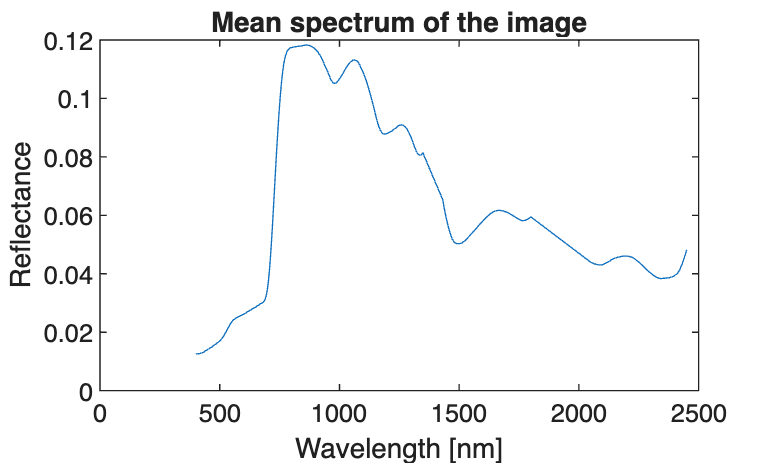

figure;
meanSpectra=std(X);

plot(wavelengths, meanSpectra);
xlabel("Wavelength [nm]");
ylabel("Reflectance");
title("Mean spectrum of the image");

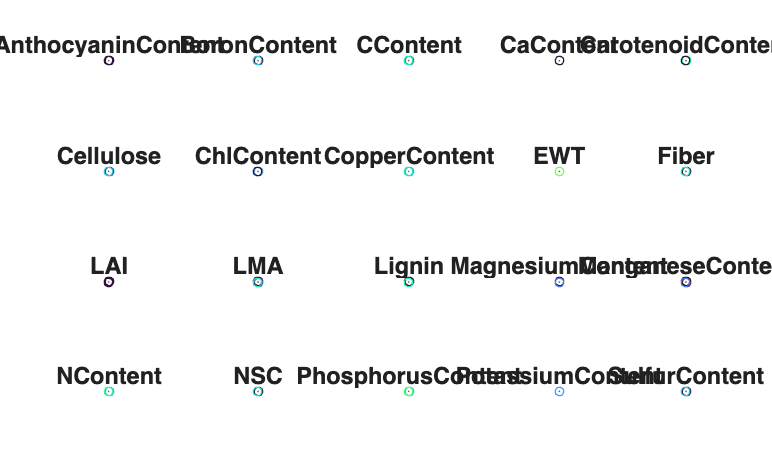

%Manual biplot taking values from biplot, so we can color it

figure;
column_names = load(fullfile("Data","variableNames.mat"));
for i = linspace(2,21,20)
    nexttile;
    color_Column = data_set{:,i};
    rgb=vals2colormap(color_Column,'turbo',[min(color_Column),max(color_Column)]);
    scatter3(bi_X,bi_Y,bi_Z,10,rgb);
   
    hold on ;
    xlabel("PC 1");
    limits =[min(bi_X), max(bi_X)];
    xlim(limits);
    ylim(limits);
    zlim(limits);
    ylabel("PC 2");
    zlabel("PC 3");
    colormap('turbo');
    set(gca,'CLim',[min(color_Column), max(color_Column)]);
    title(extractBefore(column_names.variables(i-1), "_"));
    % title(column_names(i))
    hold off
end

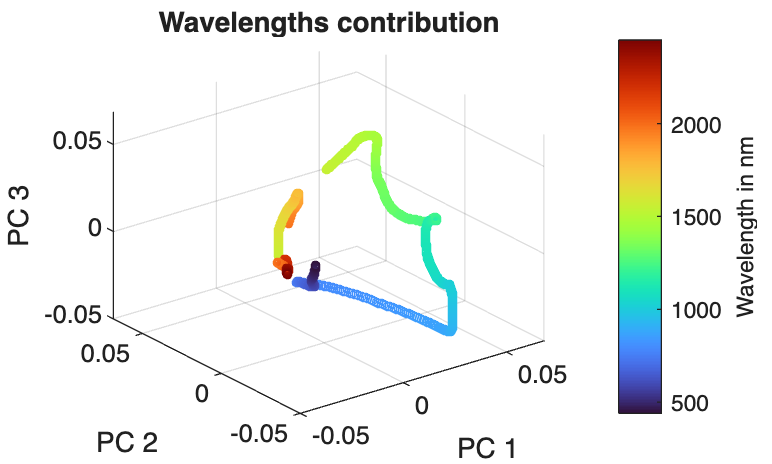

%Manual biplot showing in color the different wavelenghts contribution to
%PC

figure;
scatter3(varX,varY,varZ,10,turbo(numel(varX)));
hold on ;
scatter3(coeff(:,1),coeff(:,2),coeff(:,3), 10, turbo(numel(coeff(:,1))))
% un-comment preceding line to show the vectors of the individual
% wavelengths
xlabel("PC 1");
limits =[min(bi_X), max(bi_X)];
xlim(limits);
ylim(limits);
zlim(limits);
ylabel("PC 2");
zlabel("PC 3");
colormap('turbo');
set(gca,'CLim',[440 2450]);
c=colorbar;
c.Label.String="Wavelength in nm";
title("Wavelengths contribution");
% title(column_names(i))
hold off

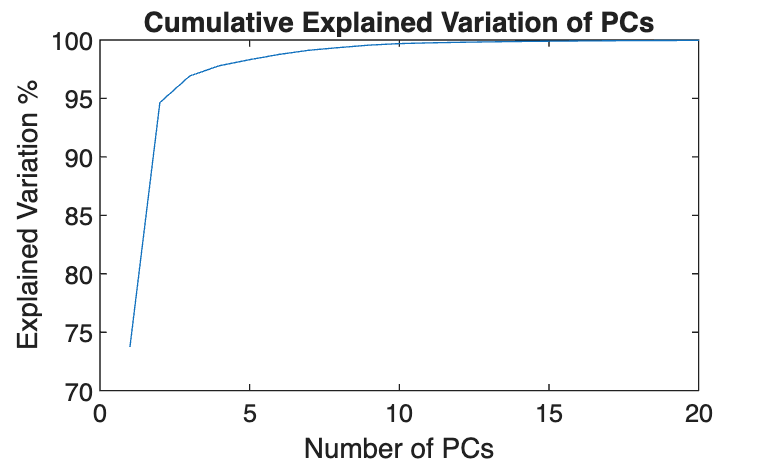

figure;
plot(cumsum(explained))
% Display the number of principal components needed
title('Cumulative Explained Variation of PCs');
xlabel("Number of PCs")
ylabel("Explained Variation %")
xlim([0,20])

%Determine number of PCs needed with 95% of variation explained
idx = find(cumsum(explained)>95,1)

idx = 3